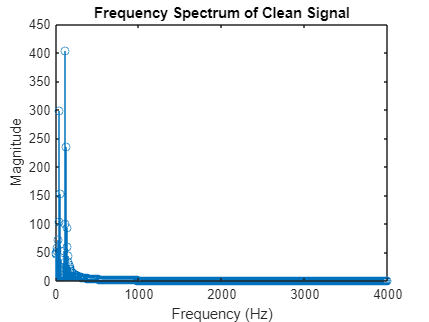

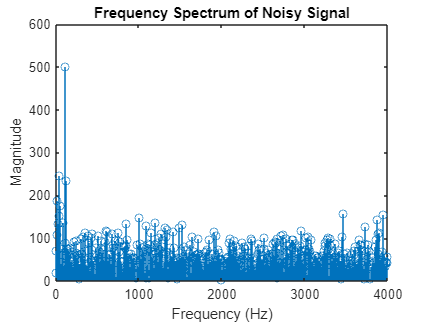

% Define the time vector for the signals
t = 0:1/8000:1;  % Assuming a duration of 1 second

% Form the signal S containing a 50 Hz sinusoid of amplitude 0.7 and a 120 Hz sinusoid of amplitude 1
S = 0.7 * sin(2*pi*50*t) + sin(2*pi*120*t);

% Corrupt the signal by adding noise
X = S + 2*randn(size(t));

% Listen to the original signal S
sound(S, 8000);

% Listen to the corrupted signal X
sound(X, 8000);

% Compute the Fast Fourier Transform (FFT) of the original signal S
nfft = 1024;
SX = fft(S, nfft);
mag_SX = abs(SX);
f_SX = (0:nfft/2)*8000/nfft;

% Compute the Fast Fourier Transform (FFT) of the corrupted signal X
X = X(:);  % Ensure X is a column vector
nfft = 1024;
X_fft = fft(X, nfft);
mag_X = abs(X_fft);
f_X = (0:nfft/2)*8000/nfft;

% Plot the frequency spectrum of the original signal S
figure;
stem(f_SX, mag_SX(1:nfft/2+1));
title('Frequency Spectrum of Signal S');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plot the frequency spectrum of the corrupted signal X
figure;
stem(f_X, mag_X(1:nfft/2+1));
title('Frequency Spectrum of Corrupted Signal X');
xlabel('Frequency (Hz)');
ylabel('Magnitude');